## 6.1 Ανίχνευση Ακμών με Sobel

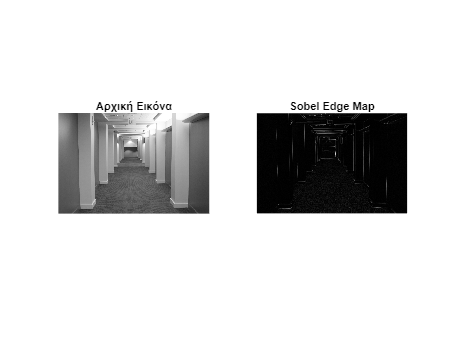

clc; clear; close all;

% 1. Φόρτωση εικόνας και μετατροπή σε grayscale
imgPath = fullfile('Images','Ασκηση 6','hallway.png');
try
    I_rgb = imread(imgPath);
catch
    % Εναλλακτικό path αν το πρώτο αποτύχει
    imgPath = 'hallway.png';
    I_rgb = imread(imgPath);
end

if size(I_rgb,3)==3
    I = rgb2gray(I_rgb);
else
    I = I_rgb;
end

% Διατήρηση του original ως double και ως uint8 για διαφορετικές χρήσεις
I_uint8 = I;
I = double(I);

% 2. Ορισμός Sobel μάσκας
Gx = [-1 0 +1;
      -2 0 +2;
      -1 0 +1];
  
Gy = [-1 -2 -1;
       0  0  0;
      +1 +2 +1];

% 3. Εφαρμογή συνέλιξης με Sobel στο x και y
% Χρήση έγκυρης συνέλιξης και επέκταση περιθωρίων για να αποφύγουμε boundary issues
I_padded = padarray(I, [1 1], 'replicate');
Sx = conv2(I_padded, Gx, 'valid');
Sy = conv2(I_padded, Gy, 'valid');

% 4. Υπολογισμός μέτρου κλίσης (έντασης ακμής)
M = sqrt(Sx.^2 + Sy.^2);

% 5. Κανονικοποίηση για εμφάνιση
M_norm = M / max(M(:));

% 6. Οπτικοποίηση
figure('Name','6.1 Sobel Edge Detection','NumberTitle','off');
subplot(1,2,1);
imshow(I_uint8);
title('Αρχική Εικόνα', 'FontWeight', 'bold');

subplot(1,2,2);
imshow(M_norm, []);
title('Sobel Edge Map', 'FontWeight', 'bold');

## 6.2 Ολική κατωφλίωση (Global Thresholding) των αποτελεσμάτων Sobel

T = graythresh(M_norm);

% Εφαρμογή του κατωφλίου στην κανονικοποιημένη εικόνα
BW = M_norm >= T; 

% Εμφάνιση του αποτελέσματος της κατωφλίωσης
fprintf('Κατώφλι Otsu (M): %.4f\n', T);

Κατώφλι Otsu (M): 0.1255


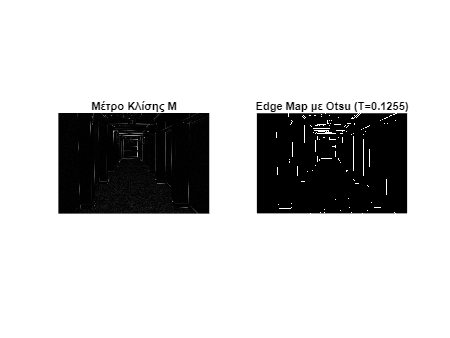


figure('Name','6.2 Global Thresholding','NumberTitle','off');
subplot(1,2,1);
imshow(M_norm, []);
title('Μέτρο Κλίσης M', 'FontWeight', 'bold');

subplot(1,2,2);
imshow(BW);
title(sprintf('Edge Map με Otsu (T=%.4f)', T), 'FontWeight', 'bold');

## Bonus: Μετασχηματισμός Hough για ανίχνευση ευθύγραμμων τμημάτων

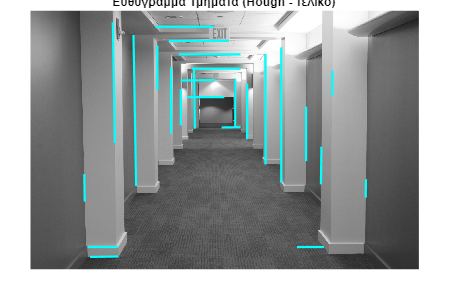

I_norm = double(I_uint8) / 255;
BW_hough = edge(I_norm, 'canny', [0.04 0.13]);

% Εφαρμογή του μετασχηματισμού Hough
[H, theta, rho] = hough(BW_hough);

P = houghpeaks(H, 40, 'Threshold', 0.15*max(H(:)));


lines = houghlines(BW_hough, theta, rho, P, 'FillGap', 20, 'MinLength', 80);


angTol = 12; % ανοχή σε μοίρες γύρω από τις 0° και 90°
keep = false(size(lines));

for k = 1:length(lines)
    th = abs(lines(k).theta);
    keep(k) = (th <= angTol) || (abs(th-90) <= angTol);
end

filtered_lines = lines(keep);

% Εμφάνιση του τελικού αποτελέσματος με τις ανιχνευμένες γραμμές
% Χρησιμοποιούμε κυανό χρώμα για καλύτερη ορατότητα σε γκρι φόντο
figure('Name','6.3 Hough Line Detection (Τελικό)','NumberTitle','off');
imshow(I_rgb);
hold on;

for k = 1:length(filtered_lines)
    xy = [filtered_lines(k).point1; filtered_lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', [0 1 1]); % Κυανό χρώμα
end

title('Ευθύγραμμα Τμήματα (Hough - τελικό)', 'FontWeight', 'bold');
hold off;